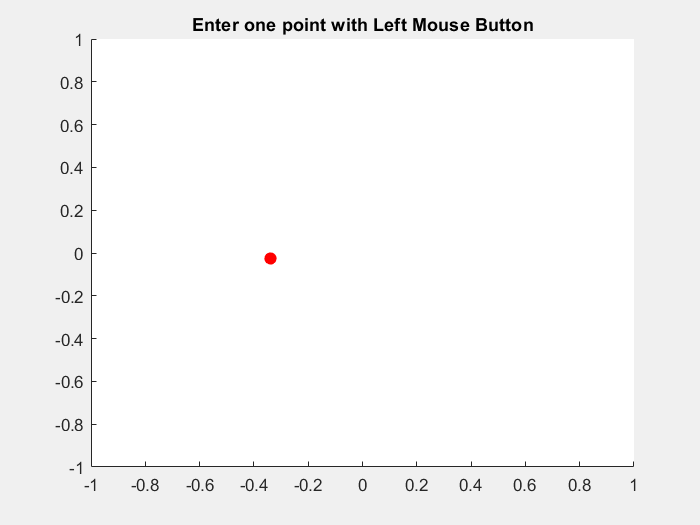

% Лабораторная работа №10
% Кирилло Дмитрий, 2 курс, 5 группа ММФ БГУ
clear;
clc
% =============================
% Пример 1
% =============================
clf
axis([-1 1 -1 1])
title('Enter one point with Left Mouse Button')
hold on
A=ginput(1);
plot(A(1),A(2),'.r','MarkerSize',25)

% =============================
% Пример 2
% =============================
clf
axis([-1 1 -1 1])
title('Enter 2 POINTS with Left Mouse Button')
hold on
A=ginput(1);
plot(A(1),A(2),'.r','MarkerSize',25)
B=ginput(1);
plot(B(1),B(2),'.b','MarkerSize',25)
plot([A(1),B(1)],[A(2),B(2)],'g')

% =============================
% Пример 3
% =============================
clf
axis([-1 1 -1 1])
title('Enter 2 POINTS')
hold on
A=ginput(1);
plot(A(1),A(2),'.r','MarkerSize',25)
text(A(1),A(2)+.1,'A','Color','r','FontWeight','bold');
B=ginput(1);
plot(B(1),B(2),'.b','MarkerSize',25)
text(B(1),B(2)+.1,'B','Color','b','FontWeight','bold');
plot([A(1),B(1)],[A(2),B(2)],'g')
t=0:0.01:1;
coords=(1-t)*A(1)+t*B(1); % Xi
coords(2,:)=(1-t)*A(2)+t*B(2); % Yi
for n=1:size(coords,2)
    h=plot(coords(1,n),coords(2,n),'.g','MarkerSize',20);
    axis([-1 1 -1 1])
    drawnow
    pause(.01)
    if(n~=1)||(n~=size(coords,2))
        set(h,'Visible','Off')
        clear h
    end
end

% =============================
% Задание 1
% =============================
clf
axis([-1 1 -1 1])
title('Enter 4 POINTS')
hold on
x1 = [];
y1 = [];
x2 = [];
y2 = [];
n = 1;
while n <= 2
    [x_i, y_i] = ginput(1);
    plot(x_i,y_i,'b.','MarkerSize', 10)    
    x1(n) = x_i
    y1(n) = y_i
    n = n+1
end

x1 = -0.4604

y1 = 0.4416

n = 2

x1 =    -0.4604    0.2284


y1 =     0.4416    0.4509


n = 3

plot(x1, y1, 'r-');
text((x1(1)+x1(2))/2,.05+(y1(1)+y1(2))/2,'A')
n=1

n = 1

while n <= 2
    [x_j, y_j] = ginput(1);
    plot(x_j,y_j,'k.','MarkerSize', 10)  
    x2(n) = x_j
    y2(n) = y_j
    n = n+1
end

x2 = -0.5856

y2 = -0.2500

n = 2

x2 =    -0.5856    0.3499


y2 =    -0.2500   -0.2687


n = 3

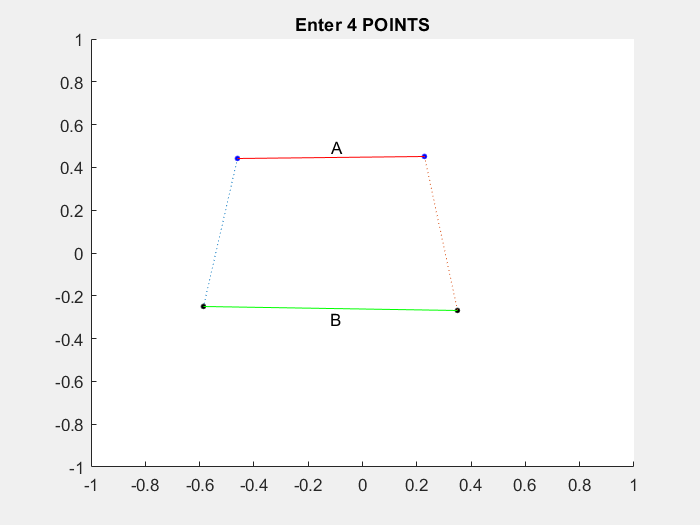

hold on;
plot(x2, y2, 'g-');
text((x2(1)+x2(2))/2,-.05+(y2(1)+y2(2))/2,'B')
t=0:0.01:1;
coords=(1-t)*x1(1)+t*x2(1); % Xi1
coords(2,:)=(1-t)*y1(1)+t*y2(1); % Yi1
F=(1-t)*x1(2)+t*x2(2); % Xi2
F(2,:)=(1-t)*y1(2)+t*y2(2); % Yi2
X1 = [x1(1) x2(1)];
Y1 = [y1(1) y2(1)];
X2 = [x1(2) x2(2)];
Y2 = [y1(2) y2(2)];
plot(X1,Y1,':',X2,Y2,':')
for n=1:size(coords,2)
    h=plot(coords(1,n),coords(2,n),'c.','MarkerSize',20);
    k=plot(F(1,n),F(2,n),'c.','MarkerSize',20);
    axis([-1 1 -1 1])
    drawnow
    pause(.01)
    if(n~=1)||(n~=size(coords,2))
        set(h,'Visible','Off')
        set(k,'Visible','Off')
        clear h
        clear k
    end
end

% =============================
% Задание 2
% =============================
clf
axis([-1 1 -1 1])
title('Enter 4 POINTS')
hold on
x1 = [];
y1 = [];
x2 = [];
y2 = [];
n = 1;
while n <= 2
    [x_i, y_i] = ginput(1);
    plot(x_i,y_i,'b.','MarkerSize', 10)    
    x1(n) = x_i
    y1(n) = y_i
    n = n+1
end

x1 = -0.7219

y1 = 0.4509

n = 2

x1 =    -0.7219    0.1694


y1 =     0.4509    0.4416


n = 3

plot(x1, y1, 'r-');
text((x1(1)+x1(2))/2,.05+(y1(1)+y1(2))/2,'A')
n=1

n = 1

while n <= 2
    [x_j, y_j] = ginput(1);
    plot(x_j,y_j,'k.','MarkerSize', 10)  
    x2(n) = x_j
    y2(n) = y_j
    n = n+1
end

x2 = -0.7440

y2 = -0.3575

n = 2

x2 =    -0.7440    0.0958


y2 =    -0.3575   -0.3061


n = 3

hold on;
plot(x2, y2, 'g-');
text((x2(1)+x2(2))/2,-.05+(y2(1)+y2(2))/2,'B')
t=0:0.01:1;
coords=(1-t)*x1(1)+t*x2(1); % Xi1
coords(2,:)=(1-t)*y1(1)+t*y2(1); % Yi1
F=(1-t)*x1(2)+t*x2(2); % Xi2
F(2,:)=(1-t)*y1(2)+t*y2(2); % Yi2
X1 = [x1(1) x2(1)];
Y1 = [y1(1) y2(1)];
X2 = [x1(2) x2(2)];
Y2 = [y1(2) y2(2)];
plot(X1,Y1,':',X2,Y2,':')
size(coords,2)

ans = 101

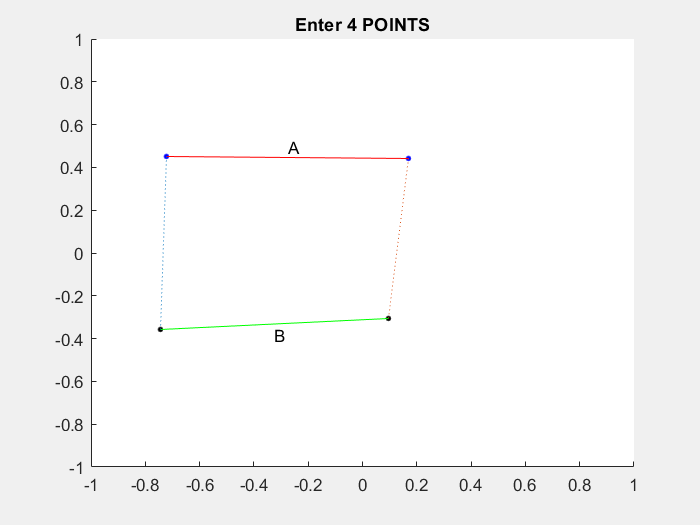

for n=1:size(coords,2)
    I = [coords(1,n) F(1,n)];
    J = [coords(2,n) F(2,n)];
    movingLine = line(I,J,'Color','yellow');
    h=plot(coords(1,n),coords(2,n),'c.','MarkerSize',20);
    k=plot(F(1,n),F(2,n),'c.','MarkerSize',20);
    axis([-1 1 -1 1])
    drawnow
    pause(.01)
    delete(movingLine)
    if(n~=1)||(n~=size(coords,2))
        set(h,'Visible','Off')
        set(k,'Visible','Off')
        clear h
        clear k
    end
end

% =============================
% Задание 3
% =============================
clf
axis([-1 1 -1 1])
title('Enter 4 POINTS')
hold on
x1 = [];
y1 = [];
x2 = [];
y2 = [];
n = 1;
while n <= 2
    [x_i, y_i] = ginput(1);
    plot(x_i,y_i,'b.','MarkerSize', 10)    
    x1(n) = x_i
    y1(n) = y_i
    n = n+1
end

x1 = -0.4899

y1 = 0.5491

n = 2

x1 =    -0.4899    0.3646


y1 =     0.5491    0.4836


n = 3

plot(x1, y1, 'r-');
text((x1(1)+x1(2))/2,.05+(y1(1)+y1(2))/2,'A')
n=1

n = 1

while n <= 2
    [x_j, y_j] = ginput(1);
    plot(x_j,y_j,'k.','MarkerSize', 10)  
    x2(n) = x_j
    y2(n) = y_j
    n = n+1
end

x2 = -0.6777

y2 = -0.2780

n = 2

x2 =    -0.6777    0.4678


y2 =    -0.2780   -0.4977


n = 3

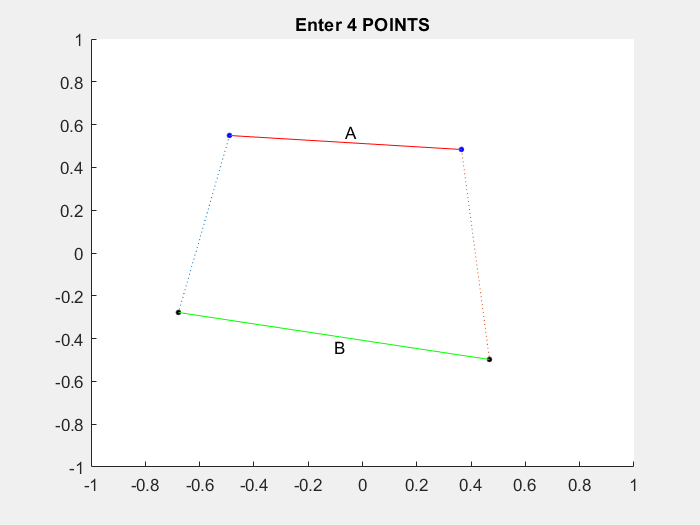

hold on;
plot(x2, y2, 'g-');
text((x2(1)+x2(2))/2,-.05+(y2(1)+y2(2))/2,'B')
t=0:0.01:1;
coords=(1-t)*x1(1)+t*x2(1); % Xi1
coords(2,:)=(1-t)*y1(1)+t*y2(1); % Yi1
F=(1-t)*x1(2)+t*x2(2); % Xi2
F(2,:)=(1-t)*y1(2)+t*y2(2); % Yi2
X1 = [x1(1) x2(1)];
Y1 = [y1(1) y2(1)];
X2 = [x1(2) x2(2)];
Y2 = [y1(2) y2(2)];
plot(X1,Y1,':',X2,Y2,':')
for n=1:size(coords,2)
    I = [coords(1,n) F(1,n)];
    J = [coords(2,n) F(2,n)];
    movingLine = line(I,J,'Color','yellow');
    h=plot(coords(1,n),coords(2,n),'c.','MarkerSize',20);
    k=plot(F(1,n),F(2,n),'c.','MarkerSize',20);
    axis([-1 1 -1 1])
    drawnow
    pause(.01)
    delete(movingLine)
    if (n~=1)||(n~=size(coords,2))
        set(h,'Visible','Off')
        set(k,'Visible','Off')
        clear h
        clear k
    end
    if n==size(coords,2)
        for k=size(coords,2):-1:1
            I = [coords(1,k) F(1,k)];
            J = [coords(2,k) F(2,k)];
            movingLine = line(I,J,'Color','yellow');
            a=plot(coords(1,k),coords(2,k),'c.','MarkerSize',20);
            b=plot(F(1,k),F(2,k),'c.','MarkerSize',20);
            axis([-1 1 -1 1])
            drawnow
            pause(.01)
            delete(movingLine)
            if(k~=1)||(k~=size(coords,2))
                set(a,'Visible','Off')
                set(b,'Visible','Off')
                clear a
                clear b
            end
        end
    end
end

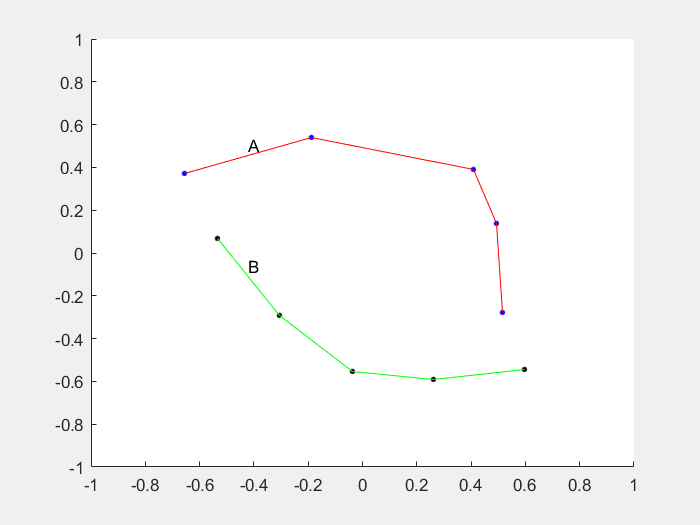

% =============================
% Задание 4
% =============================
brokenLines(5);

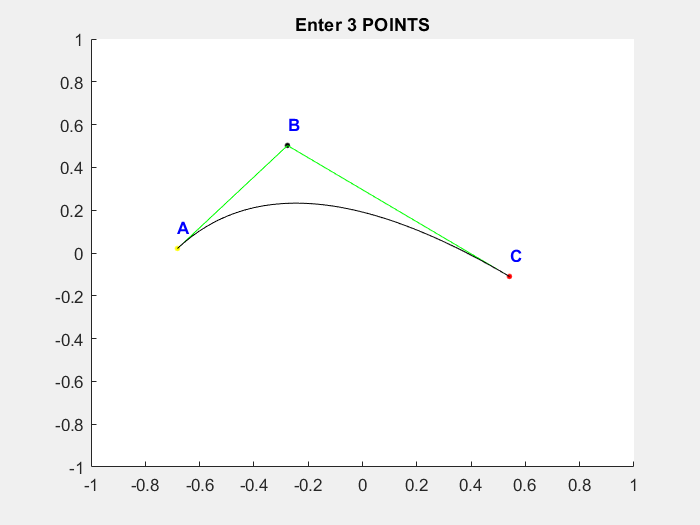

% =============================
% Задание 5
% =============================
clf
axis([-1 1 -1 1])
title('Enter 3 POINTS')
hold on
[x_i, y_i] = ginput(1);
plot(x_i,y_i,'y.','MarkerSize', 10)    
x1 = x_i;
y1 = y_i;
plot(x1, y1, 'r-');
text(x1,y1+.1,'A','Color','b','FontWeight','bold');
[x_j, y_j] = ginput(1);
plot(x_j,y_j,'k.','MarkerSize', 10)  
x2 = x_j;
y2 = y_j;
text(x2,y2+.1,'B','Color','b','FontWeight','bold');
hold on;
[x_k, y_k] = ginput(1);
plot(x_k,y_k,'r.','MarkerSize', 10)  
x3 = x_k;
y3 = y_k;
text(x3,y3+.1,'C','Color','b','FontWeight','bold');
hold on;
plot([x1 x2 x3], [y1 y2 y3],'Color','green')
t=0:0.01:1;
coords = ((1-t).^2).*x1+2*(1-t).*t.*x2+x3.*(t.^2); % Xi
coords(2,:) = ((1-t).^2).*y1+2*(1-t).*t.*y2+y3.*(t.^2); % Yi
h = animatedline;
axis([-1 1 -1 1])
for n=1:size(coords,2)
    k=plot(coords(1,n),coords(2,n),'c.','MarkerSize',20);
    addpoints(h,coords(1,n),coords(2,n));
    axis([-1 1 -1 1])
    drawnow
    pause(.01)
    if(n~=1)||(n~=size(coords,2))
        set(k,'Visible','Off')
        clear k
    end
end

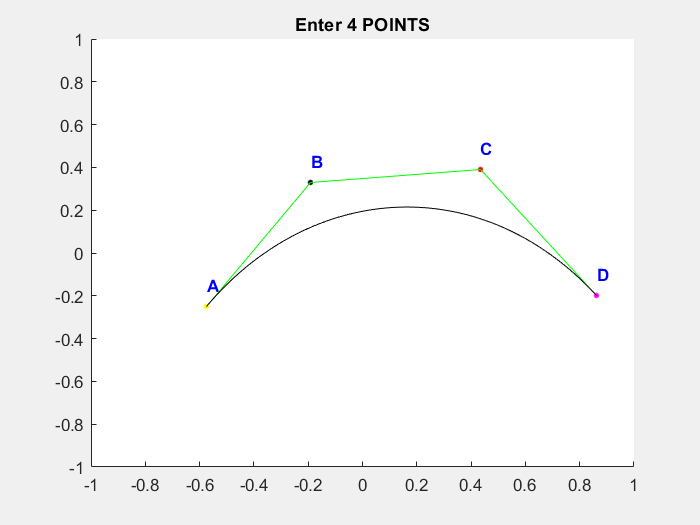

% =============================
% Задание 6
% =============================
clf
axis([-1 1 -1 1])
title('Enter 4 POINTS')
hold on
[x_i, y_i] = ginput(1);
plot(x_i,y_i,'y.','MarkerSize', 10)    
x1 = x_i;
y1 = y_i;
plot(x1, y1, 'r-');
text(x1,y1+.1,'A','Color','b','FontWeight','bold');
[x_j, y_j] = ginput(1);
plot(x_j,y_j,'k.','MarkerSize', 10)  
x2 = x_j;
y2 = y_j;
text(x2,y2+.1,'B','Color','b','FontWeight','bold');
hold on;
[x_k, y_k] = ginput(1);
plot(x_k,y_k,'r.','MarkerSize', 10)  
x3 = x_k;
y3 = y_k;
text(x3,y3+.1,'C','Color','b','FontWeight','bold');
hold on;
[x_l, y_l] = ginput(1);
plot(x_l,y_l,'m.','MarkerSize', 10)  
x4 = x_l;
y4 = y_l;
text(x4,y4+.1,'D','Color','b','FontWeight','bold');
hold on;
plot([x1 x2 x3 x4], [y1 y2 y3 y4],'Color','green')
t=0:0.01:1;
coords = ((1-t).^3).*x1+3*t.*((1-t).^2).*x2+3*(1-t).*(t.^2).*x3+x4.*(t.^3); % Xi
coords(2,:) = ((1-t).^3).*y1+3*t.*((1-t).^2).*y2+3*(1-t).*(t.^2).*y3+y4.*(t.^3); % Yi
h = animatedline;
axis([-1 1 -1 1])
for n=1:size(coords,2)
    k=plot(coords(1,n),coords(2,n),'c.','MarkerSize',20);
    addpoints(h,coords(1,n),coords(2,n));
    axis([-1 1 -1 1])
    drawnow
    pause(.01)
    if(n~=1)||(n~=size(coords,2))
        set(k,'Visible','Off')
        clear k
    end
end

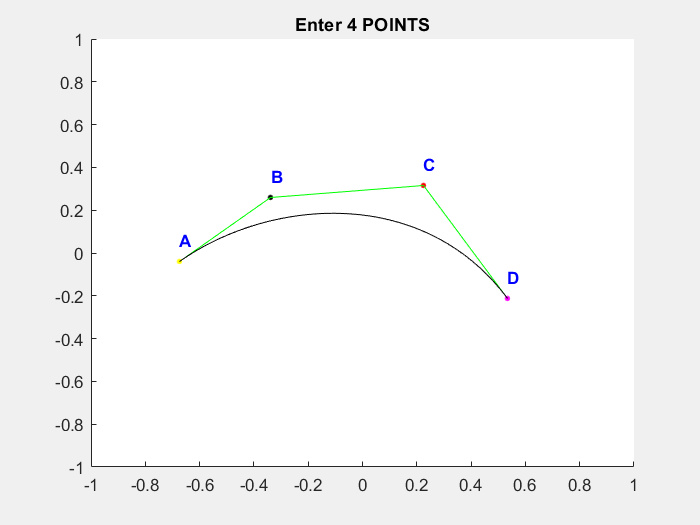

% =============================
% Задание 7
% =============================
Interpolation(4)